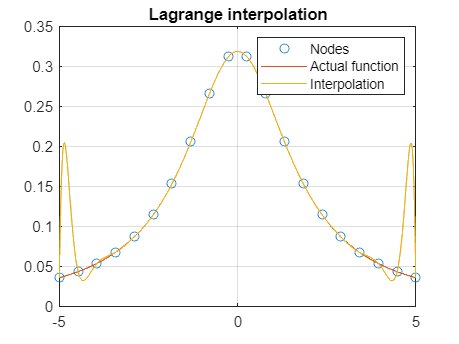

% Lagrange interpolation


m=20;
a=-5;
b=5;
x_nodes= linspace(a,b,m)';

func= @(x) 1./(pi+x.^2);
y_nodes=func(x_nodes);

n=1000;
x=linspace(a,b,n)';
y=func(x);


f_interp=zeros(n,1);

for i=1:m
    f_interp=f_interp+y_nodes(i)*Lagrange_polynomaials(x_nodes,x,i);
end

%let us find using chebyshev's nodes
xk=ones(m,1);
for i=1:m
    xk(i)=0.5*(a+b)+0.5*(a-b)*cos((2*i-1)*pi/(2*m));
end

y_che=func(xk);

f_interp2=zeros(n,1);

for i=1:m
    f_interp2=f_interp2+y_che(i)*Lagrange_polynomaials(xk,x,i);
end



plot(x_nodes,y_nodes,'o')
hold on
plot(x,y)
plot(x,f_interp)
hold off
legend('Nodes','Actual function','Interpolation')
grid on
title('Lagrange interpolation')

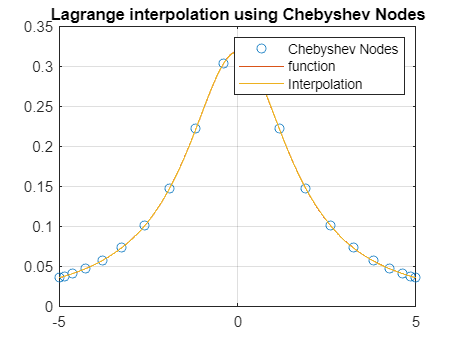


plot(xk,y_che,'o')
hold on
plot(x,y)
plot(x,f_interp2)
hold off
legend('Chebyshev Nodes','function','Interpolation')
grid on
title('Lagrange interpolation using Chebyshev Nodes')



%Error

err_lagrange=sqrt(sum((f_interp-y).^2))/length(y)

err_lagrange = 0.0011

err_chebyshev=sqrt(sum((f_interp2-y).^2))/length(y)

err_chebyshev = 7.1442e-06